clear; close all; clc

## Parameters

n_poles = 4;
n_slots = 6;
n_turns = 10;
r = 12.5e-3; %[m]
R = 20e-3; %[m]
B_pk = 0.4; %[T]

I_phase = 4;

% th_hA = 30;
% th_hB = 270;
% th_hC = 150;

off = -30;

th_hA = mod(30+off,360);
th_hB = mod(270+off, 360);
th_hC = mod(150+off, 360);

## Calculations

cnt = 1;
max_angle = 2*pi

max_angle = 6.2832

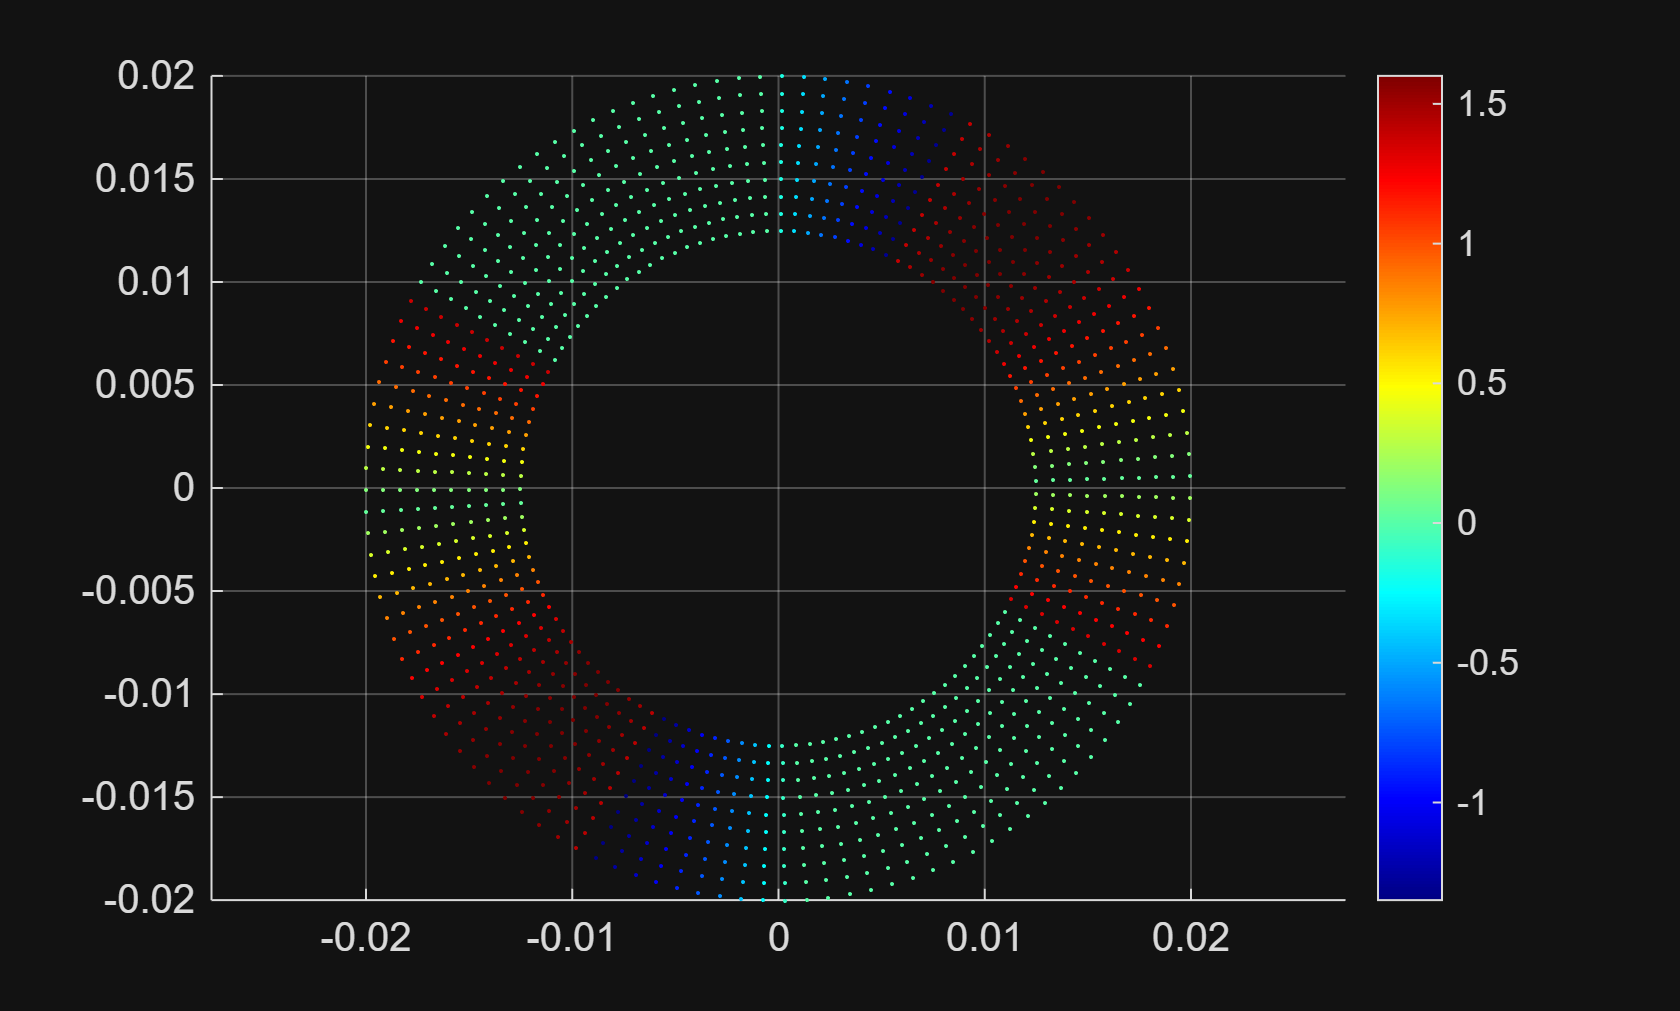

f_array = [];
for theta_off = 0:.06:max_angle
    theta = linspace(0,2*pi, n_slots*n_turns*2) + theta_off;
    
    B = @(theta) B_pk * sin(theta*n_poles/2);
    b = B(theta);
    
    Is = b_to_C(I_phase, b, [th_hA, th_hB, th_hC]);
    i = fill_currents(Is, n_slots, n_turns);
    
    f = b.*i';
    f_array = [f_array;f];
    
    mnf(cnt) = mean(f);
    smf(cnt) = sum(f);
    cnt = cnt + 1;
    % figure, hold on
    % plot_motor(f, r, R, theta)
    % axis equal
    % figure
    % plot(f)
    % yline(mean(f))
    % drawnow;
    % pause(0.1);
end
generate_motor_gif(f_array, r, R, theta, 'test.gif')

mean(mnf)
figure, hold on, grid on
plot(0:.001:max_angle,smf*(R-r)*(R+r)/2)
yline(mean(smf)*(R-r)*(R+r)/2)
yline(0)
xlabel('Angle [rad]'), ylabel('Torque [Nm]')

## Functions

function i = fill_currents(Is, n_slots, n_turns)
i = zeros(n_slots*n_turns*2, 1);
count = 1;
for s = 1:n_slots/3
    for c = 1:length(Is)
        for turn = 1:n_turns
            i(count) = Is(c);
            count = count + 1;
        end
        for turn = 1:n_turns
            i(count) = -Is(c);
            count = count + 1;
        end
    end
end
end

function Is = b_to_C(I, b, th_h)
theta_d = 360/length(b);
x = zeros(3,1);
for phase = 1:3
    x(phase) = b(1+round(th_h(phase)/theta_d)) > 0;
end
xx = x(1)*4 + x(2)*2 + x(3);
% xx = bitxor(xx,0b111);
switch xx
    case 0b110
        Is = [0, I, -I];
        
    case 0b100
        Is = [I, 0, -I];
        
    case 0b101
        Is = [I, -I, 0];
        
    case 0b001
        Is = [0, -I, I];
        
    case 0b011
        Is = [-I, 0, I];
        
    case 0b010
        Is = [-I, I, 0];
end
end
function [] = plot_motor(f, r, R, theta)
for i = 1:length(theta)
    % Generate points for the line
    x = linspace(r*sin(theta(i)), R*sin(theta(i)), 100);
    y = linspace(r*cos(theta(i)), R*cos(theta(i)), 100);
    z = linspace(f(i), f(i), 100);
    
    % Use z or f(i) as color data
    c = linspace(f(i), f(i), 100);
    
    % Plot with scatter3 and include color data
    scatter3(x, y, z, 10, c, 'filled'); 
    hold on;
end
colormap(jet);
colorbar;
end

function [] = generate_motor_gif(f_array, r, R, theta, gif_filename)
    % Create a figure
    figure;
    
    % Loop through the f_array (each set of f values corresponds to a frame)
    for k = 1:height(f_array)
        print(k)
        f = f_array(k,:); % Get the current set of f values
        
        % Clear the figure for the new plot
        clf;
        
        % Plot using the existing plot_motor function
        for i = 1:length(theta)
            % Generate points
            x = linspace(r*sin(theta(i)), R*sin(theta(i)), 10);
            y = linspace(r*cos(theta(i)), R*cos(theta(i)), 10);
            z = linspace(f(i), f(i), 10);
            
            % Use the f(i) value to define color data
            c = linspace(f(i), f(i), 10); 
            
            % Scatter plot with color data
            scatter3(x, y, z, 1, c, 'filled'); 
            hold on;
        end
        
        % Apply colormap and colorbar
        colormap(jet);
        colorbar;
        
        % Set axes limits for consistency
        xlim([-R, R]);
        ylim([-R, R]);
        view(0, 90)
        axis equal
        
        % Capture the frame
        frame = getframe(gcf);
        img = frame2im(frame);
        [imind, cm] = rgb2ind(img, 256);
        
        % Write to the GIF
        if k == 1
            imwrite(imind, cm, gif_filename, 'gif', 'Loopcount', inf, 'DelayTime', 0.1);
        else
            imwrite(imind, cm, gif_filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.1);
        end
    end
end